Total number of read CIR pairs for L1_R1_CIRs_Ch_9.txt: 223
Total number of read CIR pairs for L1_R2_CIRs_Ch_9.txt: 514
Total number of read CIR pairs for L1_R3_CIRs_Ch_9.txt: 517


CIR number 5 for L1_R1_CIRs_Ch_9.txt


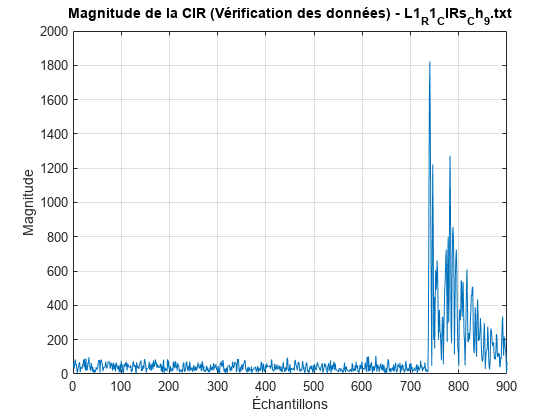

Highest sample :739
Noise variance :389.0431
Direct path :738


First Path Amplitudes: 258.9866, 399.5038, 368.988


Indexes of First Path Amplitudes: 738, 739, 740


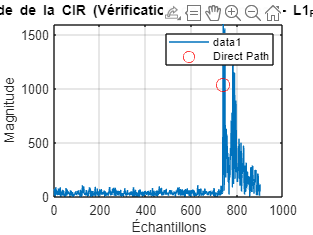

Distance estimée : 3.6 mètres


Signal Level Difference (sl_diff_ip): 14.4662


Noise Level: 37.0439


Magnitude at Direct Path: 1035.9464


Calculated Signal Level Difference (sl_diff_ip_calculated): 45.4665


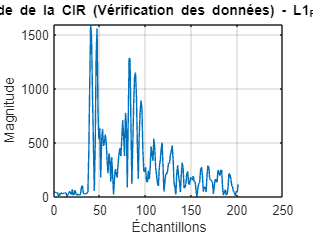

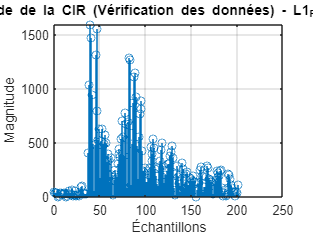

CIR number 1 for L1_R2_CIRs_Ch_9.txt


Highest sample :760
Noise variance :438.5198
Direct path :739


First Path Amplitudes: 180.7336, 73.7403, 44.5253


Indexes of First Path Amplitudes: 739, 740, 741


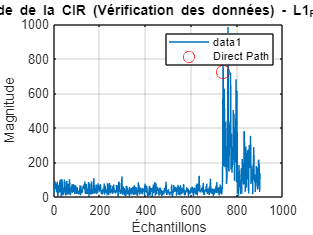

Distance estimée : 3.9 mètres


Signal Level Difference (sl_diff_ip): 12.6154


Noise Level: 39.5876


Magnitude at Direct Path: 722.9343


Calculated Signal Level Difference (sl_diff_ip_calculated): 47.069


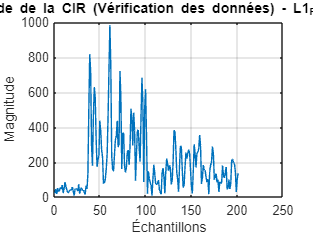

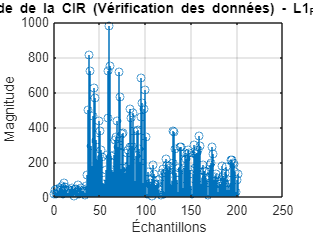

CIR number 1 for L1_R3_CIRs_Ch_9.txt


Highest sample :746
Noise variance :417.5858
Direct path :746


First Path Amplitudes: 327.4609, 299.1007, 153.2359


Indexes of First Path Amplitudes: 746, 747, 748


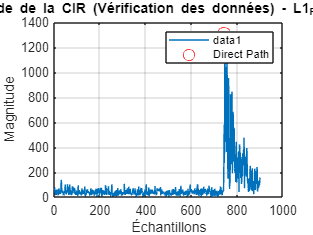

Distance estimée : 6 mètres


Signal Level Difference (sl_diff_ip): 15.2511


Noise Level: 39.094


Magnitude at Direct Path: 1309.8435


Calculated Signal Level Difference (sl_diff_ip_calculated): 45.0504


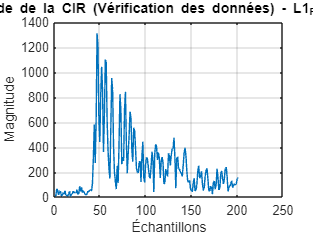

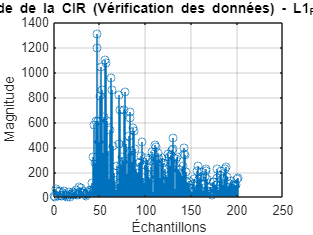

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI 

% Description : This MATLAB script reads and processes Channel Impulse 
% Response (CIR) data from multiple specified files. It calculates the 
% magnitude of the CIR, identifies the direct path for both Line-of-Sight 
% (LOS) and Non-Line-of-Sight (NLOS) conditions, and visualizes various 
% aspects of the CIR data. The user is prompted to enter the CIR number to 
% display and classify it as LOS or NLOS. The script then plots the CIR magnitude,
% highlights the direct path, and calculates related parameters such as signal level 
% differences and estimated distances. Functions are included for detecting the first
% path and calculating first path amplitudes and signal level differences.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Read files and extract data
file_paths = {'L1_R1_CIRs_Ch_9.txt', 'L1_R2_CIRs_Ch_9.txt', 'L1_R3_CIRs_Ch_9.txt'};


all_CIR_real_all = {};
all_CIR_imag_all = {};

for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurements(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

while true
    % Prompt the user for the CIR number to display
    prompt = 'Enter the CIR number you want to display (1-1087) or 0 to exit: ';
    CIRNumber = input(prompt);
    
    if CIRNumber == 0 % To quit, press 0
        break;
    end

    for i = 1:length(file_paths)
        file_path = file_paths{i};
        CIR_real_all = all_CIR_real_all{i};
        CIR_imag_all = all_CIR_imag_all{i};

        if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
            disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
            
            % Calculate CIR magnitude
            CIR_real = CIR_real_all{CIRNumber}';
            CIR_imag = CIR_imag_all{CIRNumber}';
            CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);
            
            % Display CIR magnitude
            figure;
            plot(CIR_magnitude);
            title(['CIR Magnitude (Data Verification) - ', file_path]);
            xlabel('Samples');
            ylabel('Magnitude');
            grid on;
            
            % Prompt the user to classify as LOS or NLOS
            prompt = 'Enter the condition (LOS (1)/NLOS (0)) for the displayed CIR: ';
            condition = input(prompt, 's');
            
            % Detect the First Path based on the condition
            if strcmpi(condition, '1')
                directPathIdx = findFirstPathLOS(CIR_magnitude);
            elseif strcmpi(condition, '0')
                directPathIdx = findFirstPathNLOS(CIR_magnitude);
            else
                disp('Invalid condition entered.');
                continue;
            end
            
            % Calculate and adjust the first path amplitudes
            [ip_f1, ip_f2, ip_f3, ip_f1_idx, ip_f2_idx, ip_f3_idx] = calculateFirstPathAmplitudes(CIR_real, CIR_imag, directPathIdx);
            
            % Display adjusted first path values and their indices
            disp(['First Path Amplitudes: ', num2str(ip_f1), ', ', num2str(ip_f2), ', ', num2str(ip_f3)]);
            disp(['Indexes of First Path Amplitudes: ', num2str(ip_f1_idx), ', ', num2str(ip_f2_idx), ', ', num2str(ip_f3_idx)]);
            
            % Annotate the First Path on the plot
            hold on;
            plot(directPathIdx, CIR_magnitude(directPathIdx), 'ro', 'MarkerSize', 10, 'DisplayName', 'Direct Path');
            legend('show');
            hold off;
            
            % Calculate the distance
            c = 3e8; % Speed of light (m/s)
            timePerSample = 1e-9; % Time per sample (in seconds)
            
            % Adjust the direct path index by subtracting the noise window
            noiseWindow = 726; % Size of the noise window
            adjustedDirectPathIdx = directPathIdx - noiseWindow;
            adjustedDirectPathIdx = max(adjustedDirectPathIdx, 0); % Ensure the index is non-negative
            
            % Calculate the time of flight
            timeDistance = adjustedDirectPathIdx * timePerSample;
            distance = timeDistance * c;

            % Display the result
            disp(['Estimated distance: ', num2str(distance), ' meters']);
            
            % Calculate the signal level differences
            [sl_diff_ip, noiseLevel, magnitudeAtDirectPath] = calculateSignalLevelDifference(CIR_magnitude, directPathIdx, noiseWindow);
            % (Add calculations for sl_diff_sts1 and sl_diff_sts2 if necessary)
            
            % Display debug values
            disp(['Signal Level Difference (sl_diff_ip): ', num2str(sl_diff_ip)]);
            disp(['Noise Level: ', num2str(noiseLevel)]);
            disp(['Magnitude at Direct Path: ', num2str(magnitudeAtDirectPath)]);
                     
            % Calculate signal levels RSL and FSL
            ip_cp = sum(CIR_magnitude.^2); % Total signal power
            ip_n = length(CIR_magnitude); % Number of samples
            ip_alpha = 0; % Attenuation constant, to be defined as per context
            log_constant = 0; % Logarithmic correction constant, to be defined as per context
            D = 0; % Distance constant, to be defined as per context
            
            ip_rsl = 10 * log10((ip_cp / ip_n)) + ip_alpha + log_constant + D;
            ip_fsl = 10 * log10(((ip_f1 + ip_f2 + ip_f3) / ip_n)) + ip_alpha + D;
            
            % Calculate the signal level difference
            sl_diff_ip_calculated = ip_rsl - ip_fsl;
            disp(['Calculated Signal Level Difference (sl_diff_ip_calculated): ', num2str(sl_diff_ip_calculated)]);
            
        else
            disp(['Invalid CIR number for ', file_path]);
        end
        
        % Display CIR magnitude from sample 700 onwards
        figure;
        plot(CIR_magnitude(700:end));
        title(['CIR Magnitude (Data Verification) - ', file_path]);
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;

        % Display CIR magnitude using stem plot from sample 700 onwards
        figure;
        stem(CIR_magnitude(700:end));
        title(['CIR Magnitude (Data Verification) - ', file_path]);
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;
    end
end

% Function to calculate and adjust first path amplitudes
function [ip_f1, ip_f2, ip_f3, ip_f1_idx, ip_f2_idx, ip_f3_idx] = calculateFirstPathAmplitudes(CIR_real, CIR_imag, directPathIdx)
    if directPathIdx + 2 <= length(CIR_real)
        ip_f1_idx = directPathIdx;
        ip_f2_idx = directPathIdx + 1;
        ip_f3_idx = directPathIdx + 2;
        ip_f1 = sqrt(CIR_real(ip_f1_idx)^2 + CIR_imag(ip_f1_idx)^2) / 4;
        ip_f2 = sqrt(CIR_real(ip_f2_idx)^2 + CIR_imag(ip_f2_idx)^2) / 4;
        ip_f3 = sqrt(CIR_real(ip_f3_idx)^2 + CIR_imag(ip_f3_idx)^2) / 4;
    else
        ip_f1 = NaN;
        ip_f2 = NaN;
        ip_f3 = NaN;
        ip_f1_idx = NaN;
        ip_f2_idx = NaN;
        ip_f3_idx = NaN;
        disp('Direct Path index is too close to the end of the CIR data.');
    end
end

% Function to detect the First Path for LOS condition
function directPathIdx = findFirstPathLOS(CIR_magnitude)
    noiseWindow = 726; % Initial window to estimate noise
    noiseVariance = var(CIR_magnitude(1:noiseWindow));
    thresholdFactor = 3.98; % Factor to detect significant variance increase
    threshold = noiseVariance * thresholdFactor;
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
    % Iterate over samples after the noise window to detect variance increase
    directPathIdx = noiseWindow;
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path: ', num2str(directPathIdx)]);
end

% Function to detect the First Path for NLOS
function directPathIdx = findFirstPathNLOS(CIR_magnitude)
    [pks, locs] = findpeaks(CIR_magnitude);
    highestPeakIndex = locs(find(pks == max(pks), 1));
    noiseWindow = 726; % Initial window to estimate noise
    noiseVariance = var(CIR_magnitude(1:noiseWindow));
    thresholdFactor = 3.98; % Factor to detect significant variance increase
    threshold = noiseVariance * thresholdFactor;
    directPathIdx = highestPeakIndex; % Initialize with the highest peak index
    disp(['Highest sample: ', num2str(highestPeakIndex)]);
    disp(['Noise variance: ', num2str(noiseVariance)]);
    % Adjust based on variance
    for idx = (noiseWindow + 1):length(CIR_magnitude)
        if var(CIR_magnitude((idx-noiseWindow):idx)) > threshold
            directPathIdx = idx;
            break;
        end
    end
    disp(['Direct path: ', num2str(directPathIdx)]); 
end

% Function to calculate the signal level difference
function [sl_diff, noiseLevel, magnitudeAtDirectPath] = calculateSignalLevelDifference(CIR_magnitude, directPathIdx, noiseWindow)
    noiseLevel = mean(CIR_magnitude(1:noiseWindow));
    magnitudeAtDirectPath = CIR_magnitude(directPathIdx);
    sl_diff = 10 * log10(magnitudeAtDirectPath / noiseLevel); % Use logarithmic scale (dB)
end
